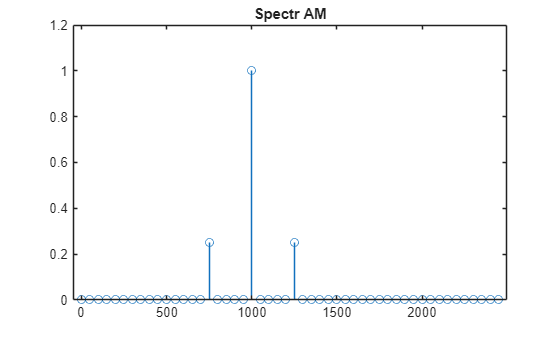

F_s = 5000;
T_s = 1/F_s;
N_pediod = 3;
n = 0:1:99;
f_1 = 250;
f_2 = 1000;
m = 0.5;
x1 = (1 + m*sin(2*pi*f_1*n*T_s)).*sin(2*pi*f_2*n*T_s);
% plot(n, signal), title("Simple AM")
X1 = fft(x1);
N_x1 = length(x1);
MOD_X1 = 2/N_x1 *abs(X1);
MOD_X1(1) = 1/N_x1 *abs(X1(1));
freq_axes = (0:N_x1-1)*F_s/N_x1;
stem(freq_axes(1:N_x1/2), MOD_X1(1:N_x1/2)), title("Spectr AM");

А теперь разберёмся с чётностью и представлением в области отрицательных частот.

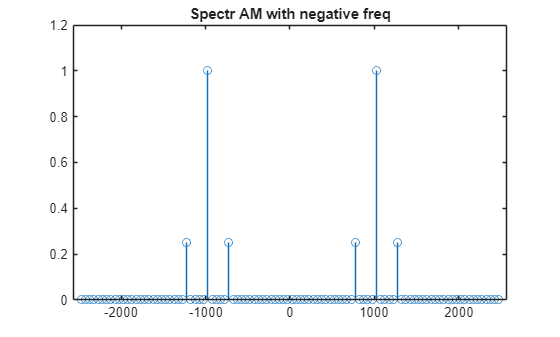

MOD_X1_shifted = fftshift(MOD_X1);
freq_axes = (-(N_x1-1)/2:(N_x1-1)/2) *F_s/N_x1;
stem(freq_axes, MOD_X1_shifted), title("Spectr AM with negative freq");

А тепреь  надо раздвинуть чатоты от нуля

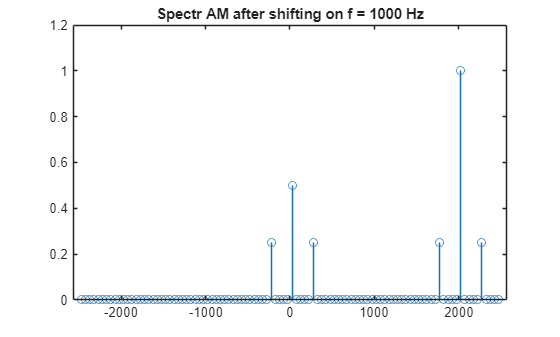

f_shift =1000;
j = sqrt(-1);
x2 = x1.*exp(j*2*pi*f_shift.*(n*T_s));
X2 = fft(x2);
N_x2 = length(x2);
MOD_X2 = 2/N_x2 *abs(X2);
MOD_X2(1) = 1/N_x2 *abs(X2(1));
MOD_X2_shifted = fftshift(MOD_X2);
freq_axes = (-(N_x2-1)/2:(N_x2-1)/2)*F_s/N_x2;
stem(freq_axes, MOD_X2_shifted), title(sprintf("Spectr AM after shifting on f = %d Hz", f_shift));

А теперь надо раздвинуть гармоники между собой.

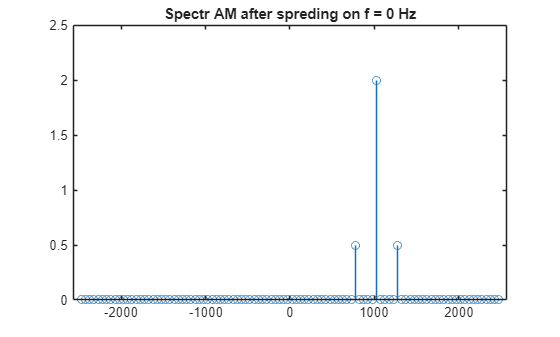

f_spreding = 0;
x1_analytic = hilbert(x1);
x3 = x1_analytic.*cos(2*pi*f_spreding.*(n*T_s));
X3 = fft(x3);

N_x3 = length(x3);
MOD_X3 = 2/N_x3 *abs(X3);
MOD_X3(1) = 1/N_x3*abs(X3(1));
MOD_X3_spreding = fftshift(MOD_X3);
freq_axes = (-(N_x3-1)/2:(N_x3-1)/2)*F_s/N_x3;
stem(freq_axes, MOD_X3_spreding), title(sprintf("Spectr AM after spreding on f = %d Hz", f_spreding));

Вывод по пункуту 3:

Получается , что не получается раздвинуть боковые полосы относительно несущей без фильтрации. 

Озадачимся вопросом вычисления линейной свёртки через циклическую.

a = [1 2 3 4 5 6];
b = [4 3 2 3];
lin_conv = conv(a, b)

lin_conv =      4    11    20    32    44    56    40    27    18



cycl_conv = fftfilt(b, a)

cycl_conv =     4.0000   11.0000   20.0000   32.0000   44.0000   56.0000


% а теперь вычислим через циклическую линейную
N_future = length(a) + length(b) -1;
A_add = fft(a, N_future);
B_add = fft(b, N_future);
add_cycl_conv = ifft(A_add.*B_add)

add_cycl_conv =     4.0000   11.0000   20.0000   32.0000   44.0000   56.0000   40.0000   27.0000   18.0000
